load ex5data1.mat

Xold = X

Xold =   -15.9368
  -29.1530
   36.1895
   37.4922
  -48.0588
   -8.9415
   15.3078
  -34.7063
    1.3892
  -44.3838


Xvalold = Xval

Xvalold =   -16.7465
  -14.5775
   34.5158
  -47.0101
   36.9751
  -40.6861
   -4.4720
   26.5336
  -42.7977
   25.3741


Xval = [ones(size(Xval, 1), 1) Xval]

Xval =     1.0000  -16.7465
    1.0000  -14.5775
    1.0000   34.5158
    1.0000  -47.0101
    1.0000   36.9751
    1.0000  -40.6861
    1.0000   -4.4720
    1.0000   26.5336
    1.0000  -42.7977
    1.0000   25.3741


X = [ones(size(X, 1), 1) X]

X =     1.0000  -15.9368
    1.0000  -29.1530
    1.0000   36.1895
    1.0000   37.4922
    1.0000  -48.0588
    1.0000   -8.9415
    1.0000   15.3078
    1.0000  -34.7063
    1.0000    1.3892
    1.0000  -44.3838


costFunct([1 1], 1, X, y)

ans = 303.9932

gradFunct([1 1], 1, X, y)

ans =   -15.3030  598.2507


options = optimset('GradObj', 'on', 'MaxIter', 400);
initial_theta = [1 1]

initial_theta =      1     1


[theta, cost] = fminunc(@(t)(master(t, 1, X, y)), initial_theta, options)


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



theta =    13.0879    0.3678


cost = 22.3795

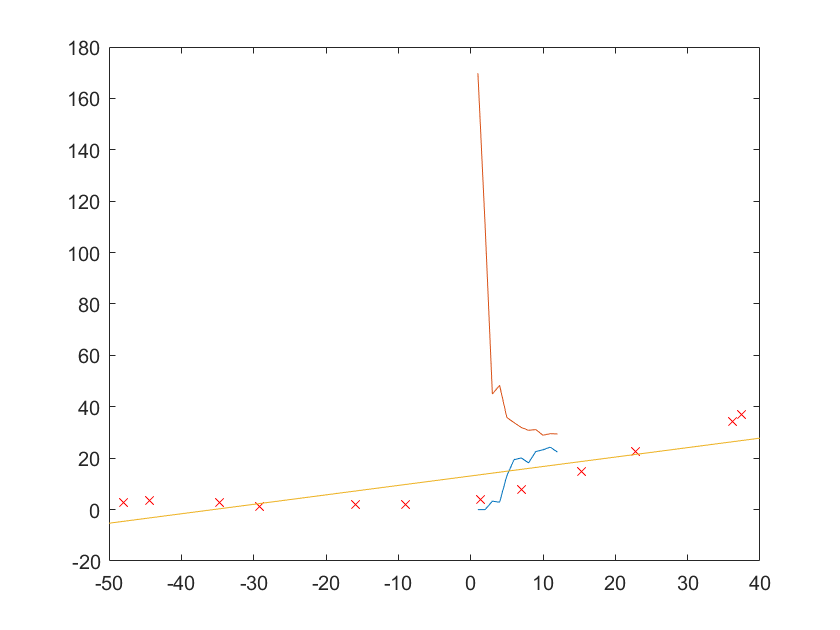

plot(X(:, 2), y, 'rx')
hold on;
q = -50:40;
p = theta(1) + theta(2)*q;
plot(q, p)
hold off

%plotting learning curves
train_error = zeros(size(X, 1), 1);
val_error = zeros(size(X, 1), 1);
initial_theta = [1 1];
for i=1:size(X, 1)
    x_new = X(1:i, :);
    y_new = y(1:i);
    [theta, cost] = fminunc(@(t)(master(t, 1, x_new, y_new)), initial_theta, options);
    train_error(i) = costFunct(theta, 0, x_new, y_new);
    val_error(i) = costFunct(theta, 0, Xval, yval);
end


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



theta =     1.0667   -0.0667


cost = 0.0022


Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>



theta =     3.2918    0.0727


cost = 0.0013


Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>



theta =    14.1546    0.5390


cost = 3.3350


Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>



theta =    14.6249    0.5598


cost = 2.8818


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



theta =    17.2137    0.4497


cost = 13.1743


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



theta =    15.4047    0.4574


cost = 19.4614


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



theta =    14.2667    0.4368


cost = 20.1121


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



theta =    14.6233    0.4231


cost = 18.1840


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



theta =    13.2965    0.4130


cost = 22.6189


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



theta =    13.8537    0.3778


cost = 23.2686


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



theta =    12.9372    0.3634


cost = 24.3233


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



theta =    13.0879    0.3678


cost = 22.3795

train_error

train_error =     0.0000
    0.0000
    3.2866
    2.8427
   13.1540
   19.4440
   20.0985
   18.1729
   22.6094
   23.2615


val_error

val_error =   169.7965
  110.3258
   44.9896
   48.3521
   35.8621
   33.8265
   31.9685
   30.8607
   31.1346
   28.9356


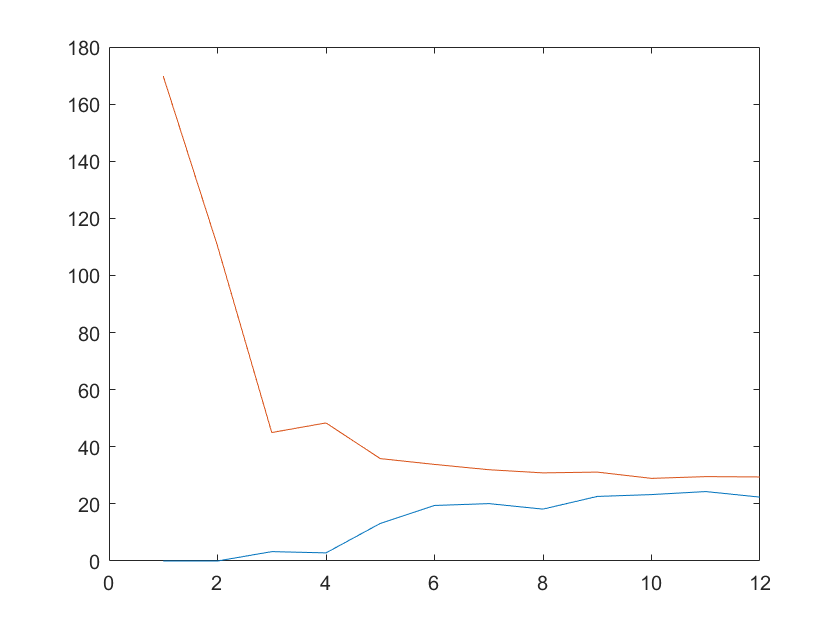

plot(train_error)
hold on
plot(val_error)
hold off

%high variance case
%preparing data set
X_new = Xold;
Xval_new = Xtest

Xval_new =   -33.3180
  -37.9122
  -51.2069
   -6.1326
   21.2612
  -40.3195
  -14.5415
   32.5598
   13.3934
   44.2099


for i=2:8
    X_new = [X_new X_new(:, 1).^i]
    Xval_new = [Xval_new Xval_new(:, 1).^i]
end

X_new = 	1.0e+03 *

   -0.0159    0.2540
   -0.0292    0.8499
    0.0362    1.3097
    0.0375    1.4057
   -0.0481    2.3097
   -0.0089    0.0799
    0.0153    0.2343
   -0.0347    1.2045
    0.0014    0.0019
   -0.0444    1.9699


Xval_new = 	1.0e+03 *

   -0.0333    1.1101
   -0.0379    1.4373
   -0.0512    2.6222
   -0.0061    0.0376
    0.0213    0.4520
   -0.0403    1.6257
   -0.0145    0.2115
    0.0326    1.0601
    0.0134    0.1794
    0.0442    1.9545


X_new = 	1.0e+05 *

   -0.0002    0.0025   -0.0405
   -0.0003    0.0085   -0.2478
    0.0004    0.0131    0.4740
    0.0004    0.0141    0.5270
   -0.0005    0.0231   -1.1100
   -0.0001    0.0008   -0.0071
    0.0002    0.0023    0.0359
   -0.0003    0.0120   -0.4180
    0.0000    0.0000    0.0000
   -0.0004    0.0197   -0.8743


Xval_new = 	1.0e+05 *

   -0.0003    0.0111   -0.3699
   -0.0004    0.0144   -0.5449
   -0.0005    0.0262   -1.3427
   -0.0001    0.0004   -0.0023
    0.0002    0.0045    0.0961
   -0.0004    0.0163   -0.6555
   -0.0001    0.0021   -0.0307
    0.0003    0.0106    0.3452
    0.0001    0.0018    0.0240
    0.0004    0.0195    0.8641


X_new = 	1.0e+06 *

   -0.0000    0.0003   -0.0040    0.0645
   -0.0000    0.0008   -0.0248    0.7223
    0.0000    0.0013    0.0474    1.7153
    0.0000    0.0014    0.0527    1.9759
   -0.0000    0.0023   -0.1110    5.3345
   -0.0000    0.0001   -0.0007    0.0064
    0.0000    0.0002    0.0036    0.0549
   -0.0000    0.0012   -0.0418    1.4509
    0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0020   -0.0874    3.8806


Xval_new = 	1.0e+06 *

   -0.0000    0.0011   -0.0370    1.2323
   -0.0000    0.0014   -0.0545    2.0659
   -0.0001    0.0026   -0.1343    6.8757
   -0.0000    0.0000   -0.0002    0.0014
    0.0000    0.0005    0.0096    0.2043
   -0.0000    0.0016   -0.0655    2.6428
   -0.0000    0.0002   -0.0031    0.0447
    0.0000    0.0011    0.0345    1.1239
    0.0000    0.0002    0.0024    0.0322
    0.0000    0.0020    0.0864    3.8201


X_new = 	1.0e+08 *

   -0.0000    0.0000   -0.0000    0.0006   -0.0103
   -0.0000    0.0000   -0.0002    0.0072   -0.2106
    0.0000    0.0000    0.0005    0.0172    0.6207
    0.0000    0.0000    0.0005    0.0198    0.7408
   -0.0000    0.0000   -0.0011    0.0533   -2.5637
   -0.0000    0.0000   -0.0000    0.0001   -0.0006
    0.0000    0.0000    0.0000    0.0005    0.0084
   -0.0000    0.0000   -0.0004    0.0145   -0.5035
    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000   -0.0009    0.0388   -1.7223


Xval_new = 	1.0e+08 *

   -0.0000    0.0000   -0.0004    0.0123   -0.4106
   -0.0000    0.0000   -0.0005    0.0207   -0.7832
   -0.0000    0.0000   -0.0013    0.0688   -3.5208
   -0.0000    0.0000   -0.0000    0.0000   -0.0001
    0.0000    0.0000    0.0001    0.0020    0.0434
   -0.0000    0.0000   -0.0007    0.0264   -1.0656
   -0.0000    0.0000   -0.0000    0.0004   -0.0065
    0.0000    0.0000    0.0003    0.0112    0.3659
    0.0000    0.0000    0.0000    0.0003    0.0043
    0.0000    0.0000    0.0009    0.0382    1.6889


X_new = 	1.0e+10 *

   -0.0000    0.0000   -0.0000    0.0000   -0.0001    0.0016
   -0.0000    0.0000   -0.0000    0.0001   -0.0021    0.0614
    0.0000    0.0000    0.0000    0.0002    0.0062    0.2246
    0.0000    0.0000    0.0000    0.0002    0.0074    0.2777
   -0.0000    0.0000   -0.0000    0.0005   -0.0256    1.2321
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0001    0.0013
   -0.0000    0.0000   -0.0000    0.0001   -0.0050    0.1748
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000   -0.0000    0.0004   -0.0172    0.7644


Xval_new = 	1.0e+10 *

   -0.0000    0.0000   -0.0000    0.0001   -0.0041    0.1368
   -0.0000    0.0000   -0.0000    0.0002   -0.0078    0.2969
   -0.0000    0.0000   -0.0000    0.0007   -0.0352    1.8029
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0004    0.0092
   -0.0000    0.0000   -0.0000    0.0003   -0.0107    0.4296
   -0.0000    0.0000   -0.0000    0.0000   -0.0001    0.0009
    0.0000    0.0000    0.0000    0.0001    0.0037    0.1191
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006
    0.0000    0.0000    0.0000    0.0004    0.0169    0.7466


X_new = 	1.0e+11 *

   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0002   -0.0026
   -0.0000    0.0000   -0.0000    0.0000   -0.0002    0.0061   -0.1790
    0.0000    0.0000    0.0000    0.0000    0.0006    0.0225    0.8130
    0.0000    0.0000    0.0000    0.0000    0.0007    0.0278    1.0413
   -0.0000    0.0000   -0.0000    0.0001   -0.0026    0.1232   -5.9212
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0020
   -0.0000    0.0000   -0.0000    0.0000   -0.0005    0.0175   -0.6065
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0017    0.0764   -3.3929


Xval_new = 	1.0e+12 *

   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0014   -0.0456
   -0.0000    0.0000   -0.0000    0.0000   -0.0001    0.0030   -0.1126
   -0.0000    0.0000   -0.0000    0.0000   -0.0004    0.0180   -0.9232
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0020
   -0.0000    0.0000   -0.0000    0.0000   -0.0001    0.0043   -0.1732
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0012    0.0388
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0002    0.0075    0.3301


X_new = 	1.0e+13 *

   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0004
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0018    0.0522
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0081    0.2942
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0104    0.3904
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0012   -0.0592    2.8457
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0002   -0.0061    0.2105
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0008   -0.0339    1.5059


Xval_new = 	1.0e+13 *

   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0046    0.1519
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0003   -0.0113    0.4268
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0018   -0.0923    4.7275
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0042
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0004   -0.0173    0.6984
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0002
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0039    0.1263
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0007    0.0330    1.4593


%normalize the data
X_new2 = bsxfun(@minus, X_new, mean(X_new))%substract mean of column elements from corresponding columns

X_new2 = 	1.0e+13 *

   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0002    0.0068   -0.4418
   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0002    0.0051   -0.3901
    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0150   -0.1480
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0173   -0.0518
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0010   -0.0524    2.4034
   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0002    0.0068   -0.4422
    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0002    0.0069   -0.4419
   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0001    0.0008   -0.2317
    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0002    0.0068   -0.4422
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0005   -0.0271    1.0637


X_new = bsxfun(@rdivide, X_new2, std(X_new))%divide the std deviation of respective column elements

X_new =    -0.3621   -0.7551    0.1822   -0.7062    0.3066   -0.5909    0.3445   -0.5085
   -0.8032    0.0013   -0.2479   -0.3270    0.0934   -0.4358    0.2554   -0.4489
    1.3775    0.5848    1.2498    0.2453    0.9784   -0.0122    0.7566   -0.1704
    1.4209    0.7066    1.3598    0.3955    1.1062    0.1256    0.8719   -0.0596
   -1.4341    1.8540   -2.0372    2.3314   -2.4115    2.6022   -2.6457    2.7661
   -0.1287   -0.9760    0.2514   -0.7397    0.3170   -0.5950    0.3458   -0.5090
    0.6806   -0.7800    0.3407   -0.7117    0.3265   -0.5918    0.3468   -0.5086
   -0.9885    0.4514   -0.6013    0.0929   -0.2185   -0.1416    0.0394   -0.2667
    0.2161   -1.0750    0.2663   -0.7434    0.3176   -0.5951    0.3458   -0.5090
   -1.3115    1.4228   -1.5481    1.4934   -1.5159    1.3887   -1.3683    1.2241


Xval_new2 = bsxfun(@minus, Xval_new, mean(Xval_new))%substract mean of column elements from corresponding columns

Xval_new2 = 	1.0e+13 *

   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0002    0.0072   -0.7176
   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0001    0.0005   -0.4427
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0014   -0.0806    3.8580
   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0004    0.0117   -0.8695
    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0003    0.0119   -0.8653
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0056   -0.1711
   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0004    0.0117   -0.8693
    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0002    0.0156   -0.7432
    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0004    0.0117   -0.8694
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0447    0.5898


Xval_new = bsxfun(@rdivide, Xval_new2, std(Xval_new))

Xval_new =    -0.9296    0.1988   -0.4045   -0.1594   -0.0131   -0.2909    0.1667   -0.3182
   -1.0782    0.5640   -0.6990    0.1720   -0.2600   -0.0758    0.0107   -0.1963
   -1.5080    1.8862   -2.0409    2.0839   -2.0736    1.9468   -1.8773    1.7109
   -0.0507   -0.9980    0.2137   -0.6487    0.2588   -0.4746    0.2729   -0.3856
    0.8350   -0.5355    0.3792   -0.5680    0.2876   -0.4622    0.2774   -0.3837
   -1.1560    0.7742   -0.8849    0.4013   -0.4470    0.1024   -0.1306   -0.0759
   -0.3226   -0.8040    0.1658   -0.6315    0.2546   -0.4733    0.2725   -0.3855
    1.2003    0.1431    0.7982   -0.2025    0.5013   -0.3146    0.3632   -0.3296
    0.5806   -0.8398    0.2580   -0.6365    0.2617   -0.4738    0.2730   -0.3855
    1.5770    1.1411    1.6710    0.8693    1.3777    0.5282    1.0416    0.2616


train_error = zeros(size(X_new, 1), 1);
val_error = zeros(size(X_new, 1), 1);
X_new = [ones(size(X_new, 1), 1) X_new]

X_new =     1.0000   -0.3621   -0.7551    0.1822   -0.7062    0.3066   -0.5909    0.3445   -0.5085
    1.0000   -0.8032    0.0013   -0.2479   -0.3270    0.0934   -0.4358    0.2554   -0.4489
    1.0000    1.3775    0.5848    1.2498    0.2453    0.9784   -0.0122    0.7566   -0.1704
    1.0000    1.4209    0.7066    1.3598    0.3955    1.1062    0.1256    0.8719   -0.0596
    1.0000   -1.4341    1.8540   -2.0372    2.3314   -2.4115    2.6022   -2.6457    2.7661
    1.0000   -0.1287   -0.9760    0.2514   -0.7397    0.3170   -0.5950    0.3458   -0.5090
    1.0000    0.6806   -0.7800    0.3407   -0.7117    0.3265   -0.5918    0.3468   -0.5086
    1.0000   -0.9885    0.4514   -0.6013    0.0929   -0.2185   -0.1416    0.0394   -0.2667
    1.0000    0.2161   -1.0750    0.2663   -0.7434    0.3176   -0.5951    0.3458   -0.5090
    1.0000   -1.3115    1.4228   -1.5481    1.4934   -1.5159    1.3887   -1.3683    1.2241


Xval_new = [ones(size(Xval_new, 1), 1) Xval_new]

Xval_new =     1.0000   -0.9296    0.1988   -0.4045   -0.1594   -0.0131   -0.2909    0.1667   -0.3182
    1.0000   -1.0782    0.5640   -0.6990    0.1720   -0.2600   -0.0758    0.0107   -0.1963
    1.0000   -1.5080    1.8862   -2.0409    2.0839   -2.0736    1.9468   -1.8773    1.7109
    1.0000   -0.0507   -0.9980    0.2137   -0.6487    0.2588   -0.4746    0.2729   -0.3856
    1.0000    0.8350   -0.5355    0.3792   -0.5680    0.2876   -0.4622    0.2774   -0.3837
    1.0000   -1.1560    0.7742   -0.8849    0.4013   -0.4470    0.1024   -0.1306   -0.0759
    1.0000   -0.3226   -0.8040    0.1658   -0.6315    0.2546   -0.4733    0.2725   -0.3855
    1.0000    1.2003    0.1431    0.7982   -0.2025    0.5013   -0.3146    0.3632   -0.3296
    1.0000    0.5806   -0.8398    0.2580   -0.6365    0.2617   -0.4738    0.2730   -0.3855
    1.0000    1.5770    1.1411    1.6710    0.8693    1.3777    0.5282    1.0416    0.2616


initial_theta = [1 1 1 1 1 1 1 1 1];
for i=1:size(X_new, 1)
    x_new2 = X_new(1:i, :);
    y_new = y(1:i);
    [theta, cost] = fminunc(@(t)(master(t, 0, x_new2, y_new)), initial_theta, options);
    train_error(i) = costFunct(theta, 0, x_new2, y_new);
    val_error(i) = costFunct(theta, 0, Xval_new, ytest);
end


Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>


Local minimum found.

Optimization completed because the 

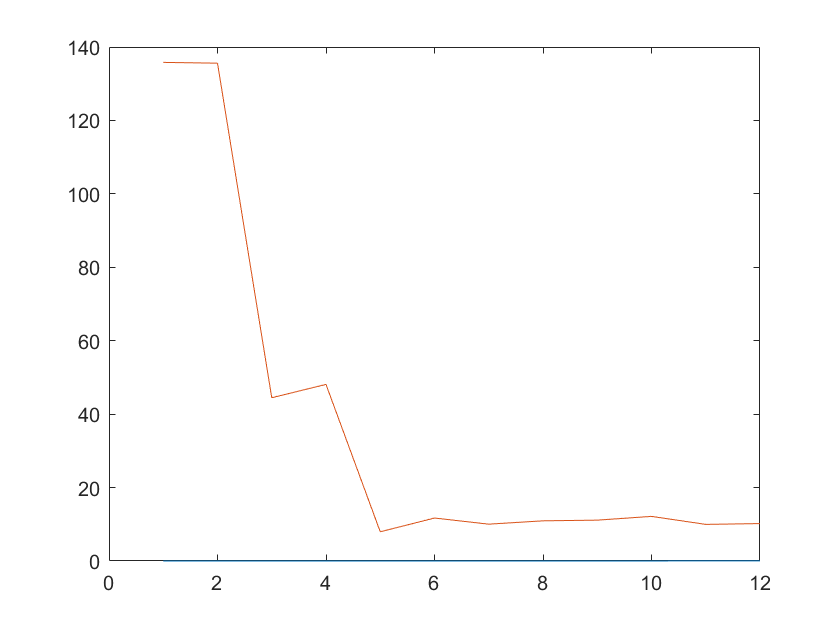

train_error;
val_error;
plot(train_error)
hold on
plot(val_error)
hold off

function cost = costFunct(theta, lambda, X, y)
    hypothesis = X*theta';%this is hypotheis if theta is a row vector
    cost = (1/(2*size(X, 1)))*sum((hypothesis - y).^2);%cost without regularisation
    cost = cost + (lambda/(2*size(X, 1)))*(sum(theta(2:end).^2));%we implement regularization here
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function grad = gradFunct(theta, lambda, X, y)
    m = size(X, 1);
    grad = zeros(1, size(X, 2));
    hypothesis = X*theta';%this is hypotheis if theta is a row vector
    for i=1:size(X, 2)
        grad(i) = (1/m)*(sum((hypothesis - y).*X(:, i)) + lambda*(theta(i)^2));    
    end
    grad(1) = grad(1) - (lambda/m)*(theta(1)^2);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [J, grad] = master(theta, lambda, X, y)
    J = costFunct(theta, lambda, X, y);
    grad = gradFunct(theta, lambda, X, y);
end